**Registration before physical activity**

clearvars;
close all;
clear all
clc
load("ECGDIANA.mat");

fs= 1000; %sampling freq
fhpass= 1; %highpass freq
flpass= 100; %lowpass freq
y= highpass(data,fhpass,fs); %highpass filter
y= lowpass(y,flpass, fs); %lowpass filter
N=length(data);
t=[0:N-1]/fs;
%Find beats per minute with findpeaks
[PKS,LOCS]= findpeaks(y, "MinPeakDistance",500);
BPM1= size(PKS,1)

BPM1 = 72

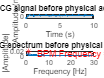


figure
subplot(2,1,1)
plot(t(1:10001),y(1:10001))
title("ECG signal before physical activity")
xlabel("Time (s)")
ylabel("Amplitude (mV)")
grid on

subplot(2,1,2)
S2 = fft(y);
tf = abs(S2(2:end))/N; %Get the magnitude
f = (0:N-1)*fs/N; %Frequency vector 
plot(f(2:end), tf);
title('ECG spectrum before physical activity')
xlabel('Frequency [Hz]')
ylabel('|Amplitude|')
xlim([0 30])
hold on
[max_value, max_index] = max(tf); 
max_freq = f(max_index);
hold on
plot(max_freq, max_value, 'r*')
text(5,0.009,"BPM Frequency = 1.1 Hz","Color","r")%texto con la frecuencia
hold off

**Registration after physical activity **

load("DIANANOREPOSO.mat");
fs= 1000; %sampling freq
fhpass= 1; %highpass freq
flpass= 100; %lowpass freq
y= highpass(data,fhpass,fs); %highpass filter
y= lowpass(y,flpass, fs); %lowpass filter
N=length(data);
t=[0:N-1]/fs;
%Encontrar el latido por minuto con findpeaks 
[PKS,LOCS]= findpeaks(y, "MinPeakDistance",500);
BPM2= size(PKS,1)

BPM2 = 102

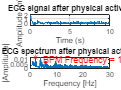

figure
subplot(2,1,1)
plot(t(1:10001),y(1:10001))
title("ECG signal after physical activity")
xlabel("Time (s)")
ylabel("Amplitude (mV)")
grid on
subplot(2,1,2)
S2 = fft(y);
tf = abs(S2(2:end))/N; 
f = (0:N-1)*fs/N; 
plot(f(2:end), tf);
title('ECG spectrum after physical activity')
xlabel('Frequency [Hz]')
ylabel('|Amplitude|')
xlim([0 30])
hold on
[max_value2, index2] = max(tf); 
max_freq2 = f(index2);
hold on
plot(max_freq2, max_value2, 'r*')
text(5,0.009,"BPM Frequency = 1.9 Hz","Color","r")
hold off

** Heart Rate: BEFORE vs AFTER**

BPM_Freq=(BPM1/60);
BPM_Freq2=(BPM2/60);
R1 = BPM2/BPM1

R1 = 1.4167


R2 = (BPM_Freq2)./(BPM_Freq)

R2 = 1.4167

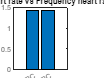


figure1 = figure("Name","Figure","Color",[1 1 1]);
axes1 = axes("Parent",figure1,...
 "Position",[0.13 0.11 0.514262714030156 0.791098901098901]);
hold(axes1,"on");
bar([R1,R2]);
ylabel("Ratio");
xlabel("Factors");
title("Temporal heart rate vs Frequency heart rate rate");
box(axes1,"on");
hold(axes1,"on");
set(axes1,"XTick",[1 2],"XTickLabel",["RC","FrecRC"]);

 set(gcf, 'Position', [100, 100, 800, 600]);